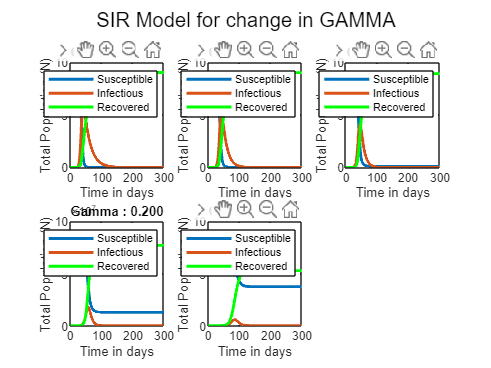

% Parameters
N = 9e7;
Io = 100;
beta = 5e-9;
gamma=0.07;
gamma1 = [0.05 0.07 0.1 0.2 0.3];
delta = 0;
days = 300;
span = 0:1/4:days;
for j = 1:5
    subplot(2,3,j);
    [S, I, R] = SIRmodel(delta,beta,gamma1(j),span,Io,N);
    plot(span,S, span,I, span,R, 'g', 'LineWidth',2);
    xlabel('Time in days');ylabel('Total Population (N)');
    legend('Susceptible','Infectious','Recovered');
    title(sprintf('Gamma : %.3f',gamma1(j)));
    sgtitle("SIR Model for change in GAMMA");
end

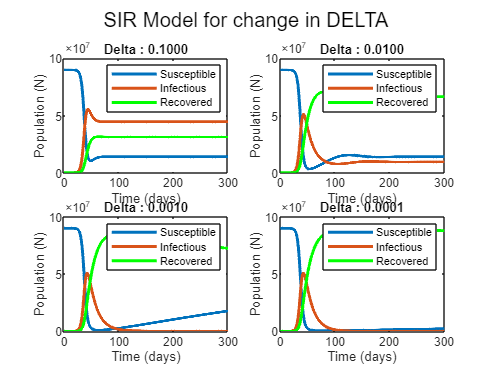


delta1 = [0.1 0.01 0.001 0.0001];
for k = 1:4
    subplot(2,2,k);
    [S, I, R] = SIRmodel(delta1(k),beta,gamma,span,Io,N);
    plot(span,S, span,I, span,R, 'g', 'LineWidth',2);
    xlabel('Time (days)');ylabel('Population (N)');
    legend('Susceptible','Infectious','Recovered');
    title(sprintf('Delta : %.4f',delta1(k)));
    sgtitle("SIR Model for change in DELTA");

end

function [S, I, R] = SIRmodel(delta,beta,gamma,span,Io,N)
S = ones(size(span));
I = zeros(size(span));
R = zeros(size(span));
I(1) = Io;
S(1) = N;
for i = 1:length(span)-1
    h = span(i+1) - span(i);
    S(i+1) = S(i) + h*(-(beta*S(i)*I(i)) + delta*R(i));
    I(i+1) = I(i) + h*((beta*S(i)*I(i)) - gamma*I(i));
    R(i+1) = R(i) + h*(gamma*I(i) -delta*R(i));
end
end